# cargar_datos_silop

Read a text file generated by the old SilopToolbox or Amore software (files with '.sl' extension).. 

## Syntax

`[medicion]= cargar_datos_silop(file)`  

## Description

`[medicion]= cargar_datos_silop(file)` `file` is the name of the file.  

The data structure is a cell array. Each element of the cell array is related to an individual sensor. Each member has the form:

 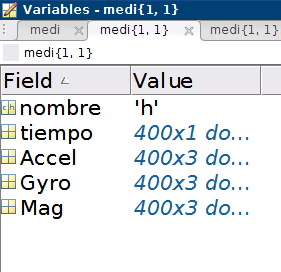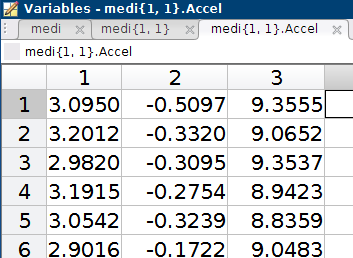

Field 'nombre' is the sensor name.  

## Examples

% Lectura de un archivo:
[medi] = cargar_datos_silop('../simur_data/test_flexionmunecacodo.sl')

medi = 1×4 cell array
    {1×1 struct}    {1×1 struct}    {1×1 struct}    {1×1 struct}


% Cada uno de los elementos del cell array se corresponde a un sensor.
% En este caso h indica el sensor del hombro, b el del brazo, a el del
% antebrazo y m el de la mano
medi{1}

ans = struct with fields:
    nombre: 'h'
    tiempo: [3000×1 double]
     Accel: [3000×3 double]
      Gyro: [3000×3 double]
       Mag: [3000×3 double]



medi{2}

ans = struct with fields:
    nombre: 'b'
    tiempo: [3000×1 double]
     Accel: [3000×3 double]
      Gyro: [3000×3 double]
       Mag: [3000×3 double]


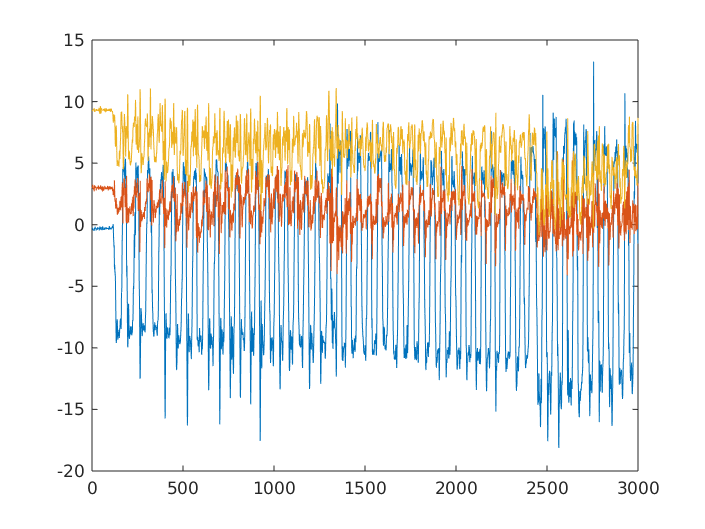


% Representa loa acelerometros:
plot(medi{4}.Accel)

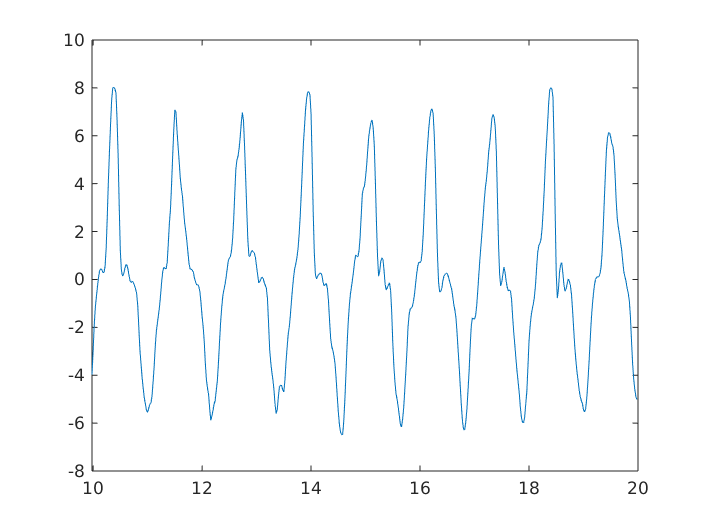

% El giroscopio en Y:
plot(medi{4}.tiempo(500:1000),medi{4}.Gyro(500:1000,2))